# Quantum Machine Learning (Grover-based) for Graph Coloring

clc; clear all; close all;


## Target Graph

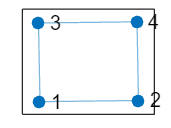

g = graph([2 2 3 3],[1 4 1 4]);

figure(1);
set(gcf,color=[1 1 1]);
plot(g);

## Oracle Design - one edge

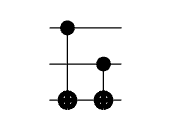

xorInnerGates = [cxGate(1,3);
                cxGate(2,3)];

xorGate = quantumCircuit(xorInnerGates,Name='XOR');

figure(2);
set(gcf,color=[1 1 1]);
plot(xorGate);

## Expansion to all edges

[startNodes endNodes] = findedge(g);
n = numnodes(g);
e = numedges(g);

gates = [];
for k=1:e
    gates = [gates;
        compositeGate(xorGate,[startNodes(k),endNodes(k),n+k])];
end


## Final Oracle 

lastQubit = n+e+1;
gate1 = [gates;mcxGate(n+(1:e),lastQubit,[])];

oracle=quantumCircuit(gate1,lastQubit);
oracle.Name='Oracle'

oracle =   quantumCircuit - 속성 있음:

    NumQubits: 9
        Gates: [5×1 quantum.gate.CompositeGate]
         Name: "Oracle"


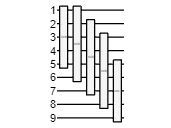


figure(3);
set(gcf,color=[1 1 1]);

plot(oracle);


## Diffuser Circuit

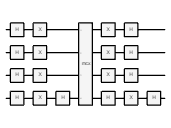

diffuserG = diffuser(n);

figure(4);
set(gcf,color=[1 1 1]);
plot(diffuserG);

## Quantum Machine Learning (with Grover)

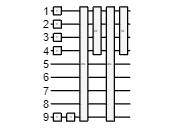

% New 
gates= [hGate(1:n);
       xGate(oracle.NumQubits);
       hGate(oracle.NumQubits)];
gates=[gates;
      compositeGate(oracle,1:9);
      compositeGate(diffuserG,1:4);
      compositeGate(oracle,1:9);
      compositeGate(diffuserG,1:4);];

c= quantumCircuit(gates);

figure(5);
set(gcf,color=[1 1 1]);
plot(c,"QubitBlocks",[8,1]);

## Simulate / Answer

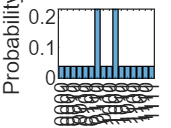

s=simulate(c);
histogram(s,1:4);

## Diffuser Function

function cg=diffuser(n)
    gates = [hGate(1:n);
            xGate(1:n);
            hGate(n);
            mcxGate(1:n-1,n,[]);
            hGate(n);
            xGate(1:n);
            hGate(1:n);
            ];
    cg = quantumCircuit(gates,Name='Diffuser');
end

